imgarray=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

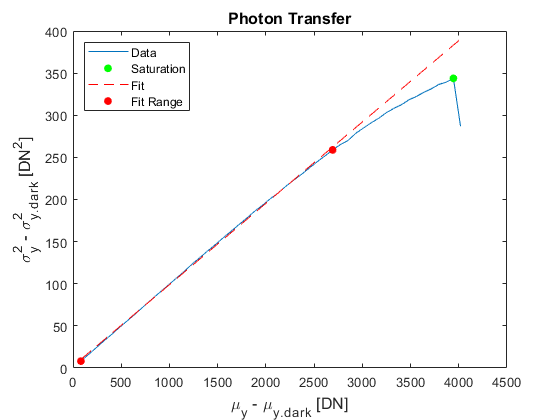

mean_dark = 29.4063

var_dark = 9.0780

K = 0.0966

[mean_dark,var_dark,K]=photonTransfer_curve_EMVA1288_mono(imgarray) 

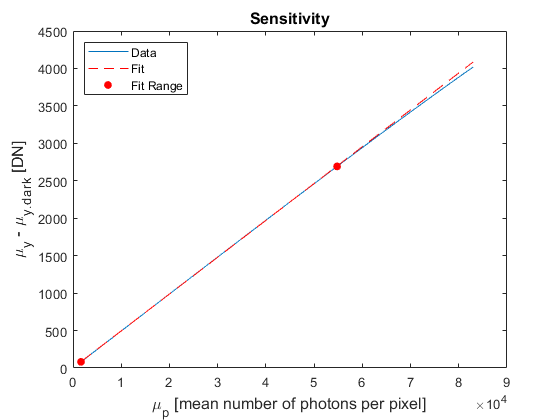

R = 0.0492

mu_p_sat = 8.1323e+04

[R,mu_p_sat]=sensitivity_curve_mono(imgarray,1659.66)

quantum_efficiency=R/K

quantum_efficiency = 0.5095

sigma_d=compute_temporaldarknoise(var_dark,(1/12)^2,K)

sigma_d = 31.1912

mu_p_min=absolute_sensitivity_threshold(quantum_efficiency,var_dark,K)

mu_p_min = 62.2267

mu_e_sat=saturation_capacity(quantum_efficiency,mu_p_sat)

mu_e_sat = 4.1432e+04

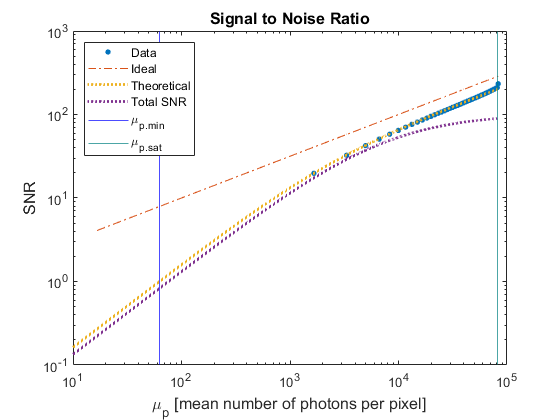

SNR_max = 203.5497

DR = 1.3069e+03

[SNR_max,DR]=plot_SNR(imgarray,1659.66,mu_p_min,mu_p_sat,mu_e_sat,sigma_d,(1/12)^2,K,quantum_efficiency,21.7,0.01)

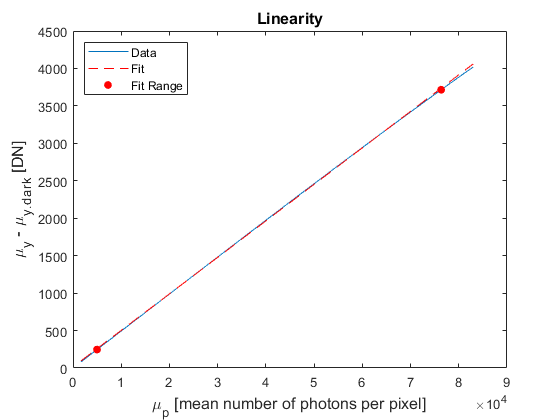

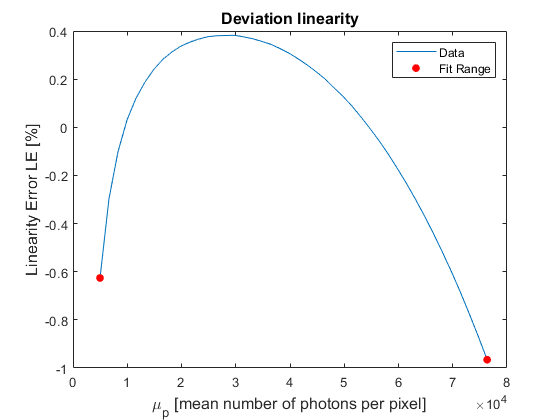

LE_min = -0.9656

LE_max = 0.3818

[LE_min,LE_max]=linearity(imgarray,1659.66)

DSNU, PRNU 

imgarray_dark=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);

imgarray_50=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);

mean_50=mean_singleimage(imgarray_50{4})

mean_50 = 2.0756e+03

mean_dark=mean_singleimage(imgarray_dark{4})

mean_dark = 29.4062


avg__50=average_image(imgarray_50);
avg_dark=average_image(imgarray_dark);

% sv_50_s=spatialvariance_singleimage(avg_50,mean_50)

sv_50_s = 325.2889

% sv_dark_s=spatialvariance_singleimage(avg_dark,mean_dark)

sv_dark_s = 3.4600

% 
% sv_50=stack_variance(imgarray_50)

sv_50 = 210.0982

% sv_dark=stack_variance(imgarray_dark)

sv_dark = 9.0819

[DSNU,PRNU,sv_50,sv_dark]=DSNU_PRNU(imgarray_dark,imgarray_50,K)